# Intent Recognition using Vocal Recordings: Neural Network Classification based on Raw Audio Signals

**Michele Ferrari [*****21118273*****]**

**06/11/2021**

## Introduction

The task is to classify voice recordings into three different classes:

- Approval

- Prohibition

- Attention

Data come from two datasets: *Kismet* and *BabyYears*.

## 1. Data Import

Automatically import all `.wav` files and organize them in proper data structures.

clear; close all; clc
import_data_Kismet
import_data_BabyEars
clearvars

## 2. Data Visualization

Use Kismet Dataset and subject CY as an example.

load kismet_WAV.mat
load babyYears_WAV.mat

### 2.1 Display signal in the time domain

Example of the content of `.wav` files. It is the raw signal, as registered by the microphone.

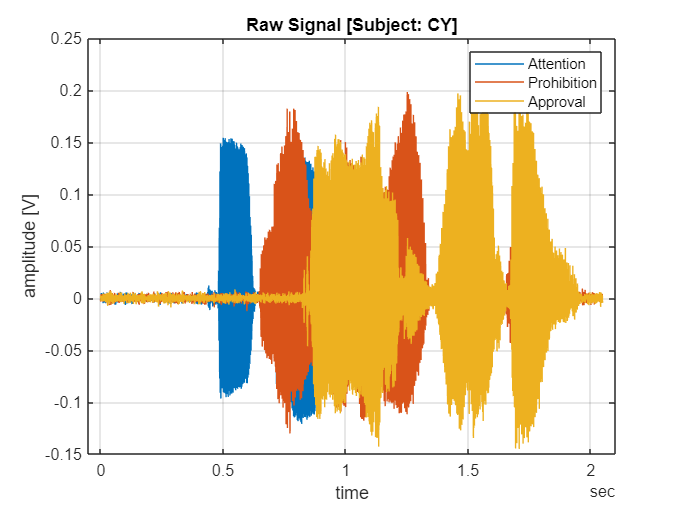

figure

data_at = kismet_WAV(1).Data;
label = kismet_WAV(1).Label;
subject = kismet_WAV(1).Subject;
plot(data_at.time, data_at.amplitude)

hold on

data_pw = kismet_WAV(5).Data;
label = kismet_WAV(5).Label;
subject = kismet_WAV(5).Subject;
plot(data_pw.time, data_pw.amplitude)

data_ap = kismet_WAV(12).Data;
label = kismet_WAV(12).Label;
subject = kismet_WAV(12).Subject;
plot(data_ap.time, data_ap.amplitude)

xlabel('time')
ylabel('amplitude [V]')
grid on
legend('Attention','Prohibition','Approval')
title(['Raw Signal [Subject: ' upper(subject) ']'])

### 2.2 Basic spectral information about the wav signal

Here the Power Spectral Density and the spectrogram of the signals are displayed, in order to show the spectral differences among different classes. This information will be used to classify signals.

**Attention**

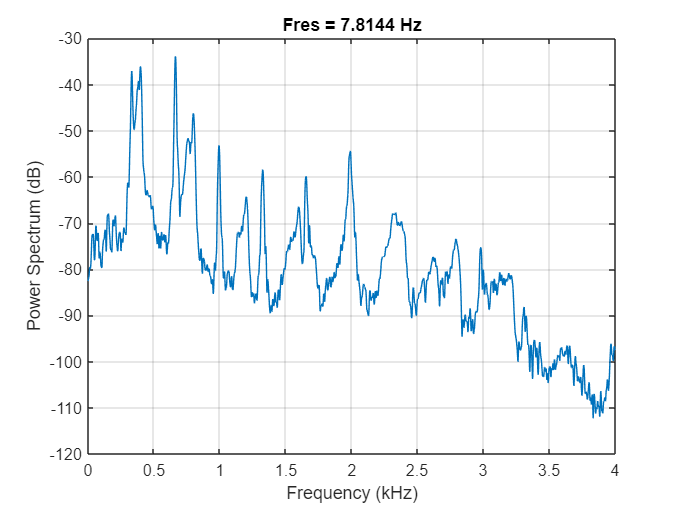

figure
show_psd_at

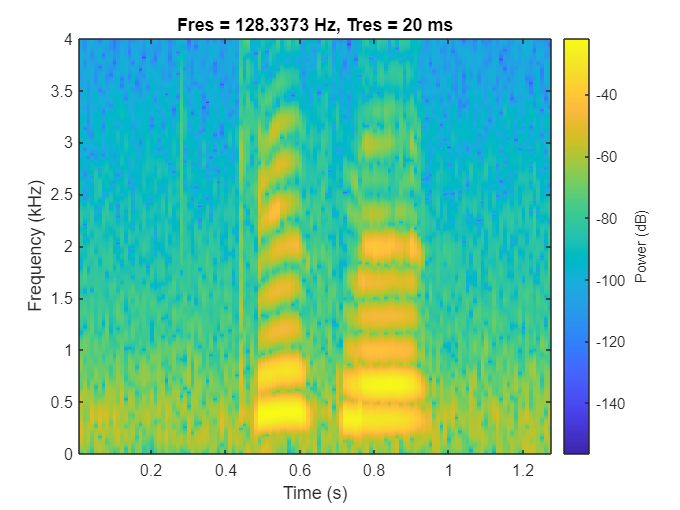

show_spectrogram_at

**Prohibition**

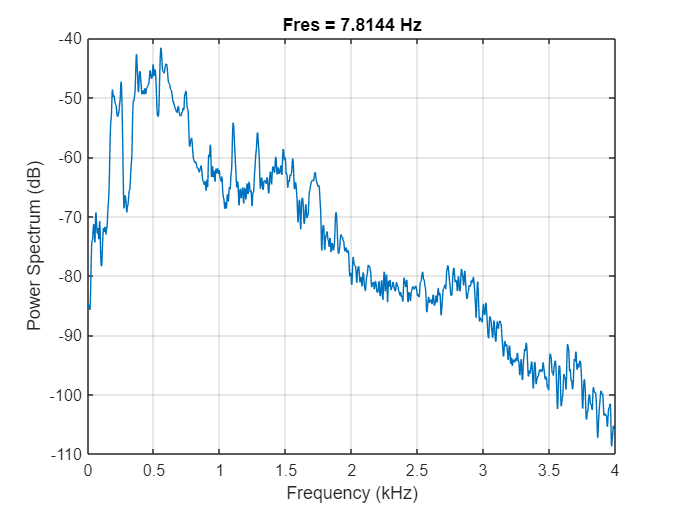

figure
show_psd_pw

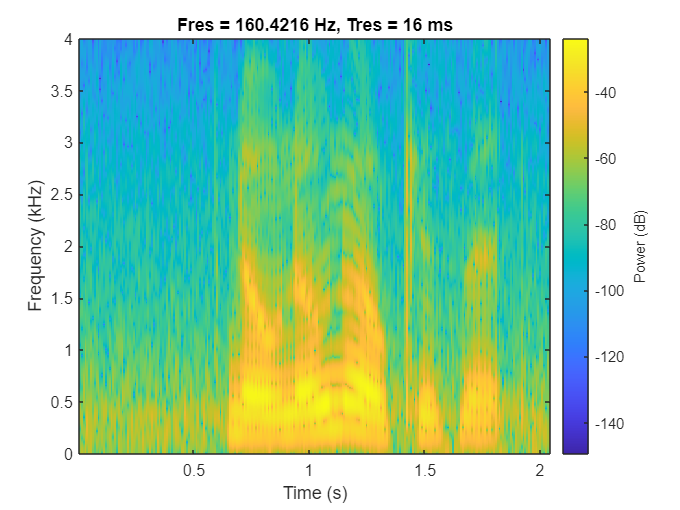

show_spectrogram_pw

**Approval**

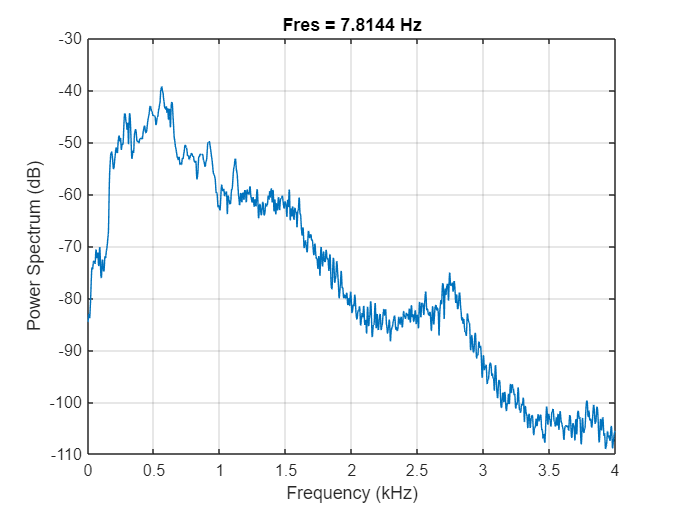

figure
show_psd_ap

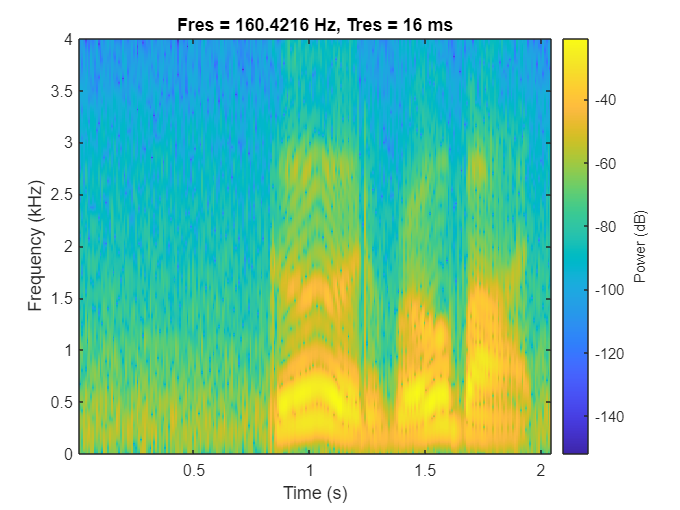

show_spectrogram_ap

### 2.3 Visualize relevant features of the audio signals

The following LiveScript Task allows the user to interactively choose audio features from a given signal. This automatic extraction will be used later to create the training and test features. Here the Live Task is just reported to show which audio features can be extracted and which parameteres ca be tuned.

A brief explanation of some relevant audio features can be found in the following source:

*Devopedia. 2021. "Audio Feature Extraction." Version 8, May 23. Accessed 2021-09-09. *[*https://devopedia.org/audio-feature-extraction*](https://devopedia.org/audio-feature-extraction)

example_at = data_at.amplitude;
example_pw = data_pw.amplitude;
example_ap = data_ap.amplitude;

% Create and set up an audioFeatureExtractor object
extractor = audioFeatureExtractor("SampleRate",kismet_fs, ...

   Output column mapping

           melSpectrum: 1:32
                  mfcc: 33:45
      spectralCentroid: 46
         spectralCrest: 47
      spectralFlatness: 48
          spectralFlux: 49
      spectralSkewness: 50
         spectralSlope: 51


    "SpectralDescriptorInput","melSpectrum", ...
    "melSpectrum",true,"mfcc",true, ...
    "spectralCentroid",true,"spectralCrest",true, ...
    "spectralFlatness",true,"spectralFlux",true, ...
    "spectralSkewness",true,"spectralSlope",true);

% Extract features from audio data
features2 = extract(extractor,example);

## 3. Signal Preprocessing

Signals are preprocessed, accomplishing two different goals:

- removing the voice-free part at the beginning and at the end of the signal, to keep only the relevant portion of the audio recording

- smoothing the signal using a moving-average filter, to remove part of the measurement noise

In order to remove the voice-free portion of the signals, the spectral energy of the signal has been computed only samples corresponding to values above a given threshold have been kept.

Some samples for which the algorithm does not detect significant spectral energy values are removed as well, in order to obtain a cleaner dataset.

load kismet_WAV.mat
load babyYears_WAV.mat

signal_preprocessing

Removed sample #111
Removed sample #128
Removed sample #152
Removed sample #156
Removed sample #158
Removed sample #33
Removed sample #50
Removed sample #75
Removed sample #80
Removed sample #85
Removed sample #86
Removed sample #103
Removed sample #121
Removed sample #121
Removed sample #132
Removed sample #135
Removed sample #135
Removed sample #138
Removed sample #149
Removed sample #154
Removed sample #161
Removed sample #164
Removed sample #166
Removed sample #167
Removed sample #169
Removed sample #169
Removed sample #169
Removed sample #169
Removed sample #171
Removed sample #171
Removed sample #171
Removed sample #171
Removed sample #172
Removed sample #172
Removed sample #172
Removed sample #180
Removed sample #180
Removed sample #183
Removed sample #183
Removed sample #185
Removed sample #187
Removed sample #188
Removed sample #188
Removed sample #189
Removed sample #190
Removed sample #192
Removed sample #192
Removed sample #192
Removed sample #194
Removed sample #199
Remove

clearvars

## 4. Feature Extraction

Features are extracted from preprocessed signals following two different approaches:

- Extraction of multiple spectral features, to be fed separately to a Neural Network for classification

- Extraction of the spectrograms of the audio recordings and their resizing to equal dimensions, so that they can be seen as images to be fed to the *imageInputLayer *of the Neural Network

Both approaches have been tested, but in the following sections only the second one is developed.

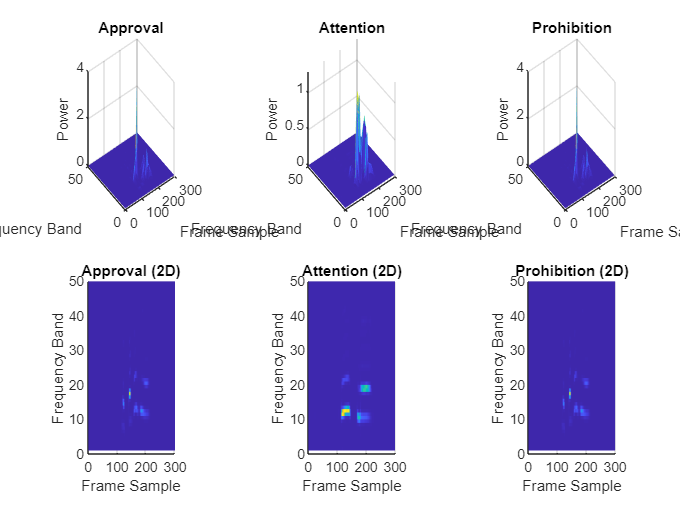

load kismet.mat
load babyYears.mat

% feature_extraction            % Extraction of audio features
feature_extraction_spectrogram  % Extraction of the spectrogram and its representation as image to classify

clearvars

## 5. Training and Test Datasets, Feature Normalization and PCA

Datasets are split into training and test sub-sets, according to different criteria:

- Intra-corpus approach

- Cross-corpus approach

- Pooling approach

Features are normalized with respect to training data and, just in the case of multiple spectral features and not of plain spectrograms, a PCA is carried out to understand which predictors contribute the most in explaining the total variance in the dataset.

Since here we are dealing with the spectrogram approach, no PCA is executed.

load features_kismet.mat
load features_babyYears.mat

training_percentage = 0.6;

% Select the task you want to perform
% TASK FLAG:
task_selection = "Baby_Kismet_vs_Baby";

switch task_selection

### 5.1 Intra-corpus Approach

#### 5.1.1 Train on Kismet, Test on Kismet

    case "Kismet_vs_Kismet"
        [features_train,labels_train,features_test,labels_test] = random_extraction(features_kismet,labels_kismet,training_percentage);

#### 5.1.2 Train on BabyYears, Test on BabyYears

    case "Baby_vs_Baby"
        [features_train,labels_train,features_test,labels_test] = random_extraction(features_babyYears,labels_babyYears,training_percentage);

### 5.2 Cross-corpus Approach

#### 5.2.1 Train on Kismet, Test on BabyYears

    case "Kismet_vs_Baby"
        features_train = features_kismet;
        labels_train = labels_kismet;
        features_test = features_babyYears;
        labels_test = labels_babyYears;

#### 5.2.2 Train on BabyYears, Test on Kismet

    case "Baby_vs_Kismet"
        features_train = features_babyYears;
        labels_train = labels_babyYears;
        features_test = features_kismet;
        labels_test = labels_kismet;

### 5.3 Pooling Approach

#### 5.3.1 Train on Kismet and BabyYears, Test on Kismet

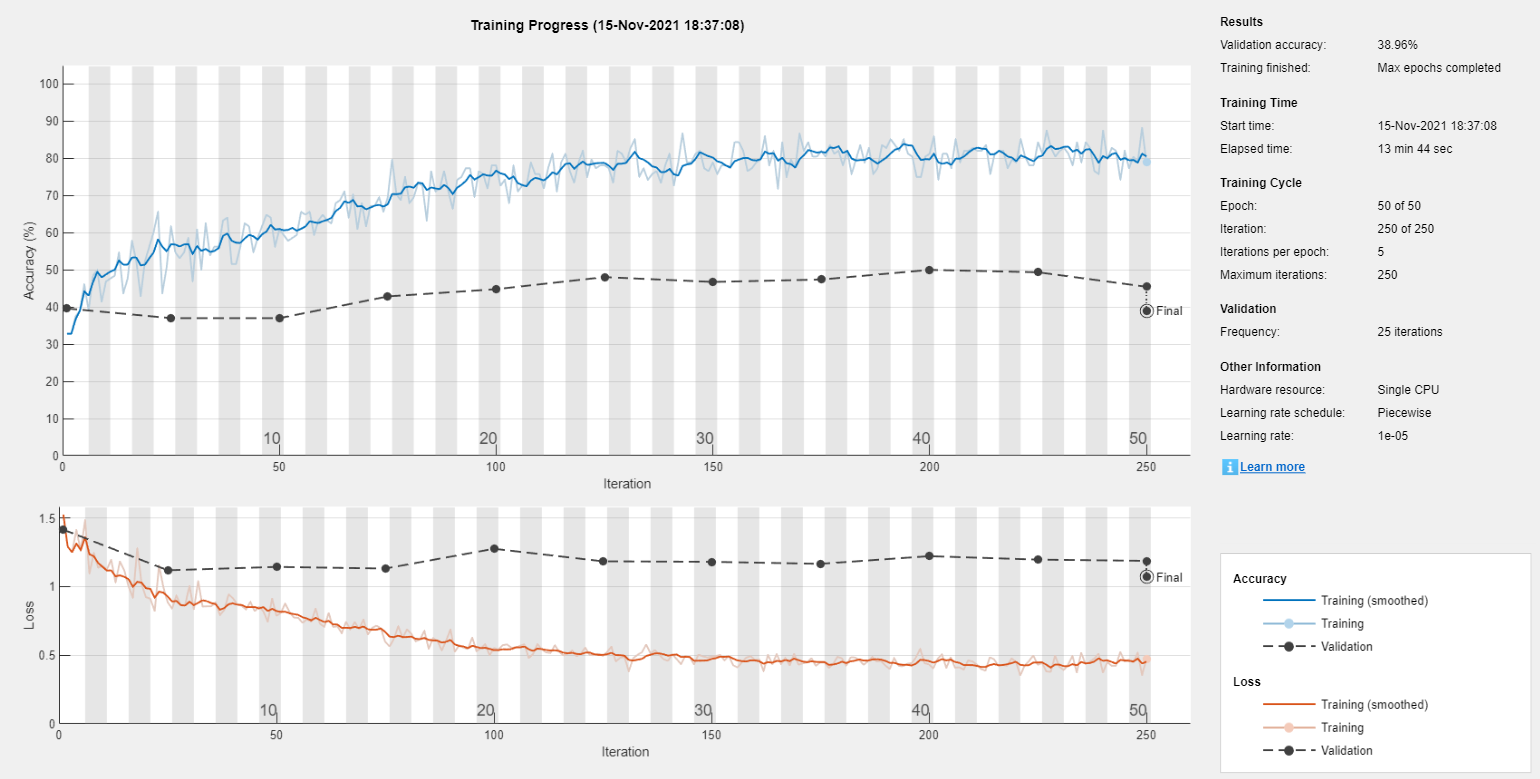

    case "Kismet_Baby_vs_Kismet"

        [features_train,labels_train,features_test,labels_test] = random_extraction(features_kismet,labels_kismet,training_percentage);
        features_train = [features_train features_babyYears];
        labels_train = [labels_train labels_babyYears];

#### 5.3.2 Train on Kismet and BabyYears, Test on BabyYears

    case "Baby_Kismet_vs_Baby"
        [features_train,labels_train,features_test,labels_test] = random_extraction(features_babyYears,labels_babyYears,training_percentage);
        features_train = [features_train features_kismet];
        labels_train = [labels_train labels_kismet];

end % End of switch statement

accuracy = 38.9610

### 5.4 Normalization

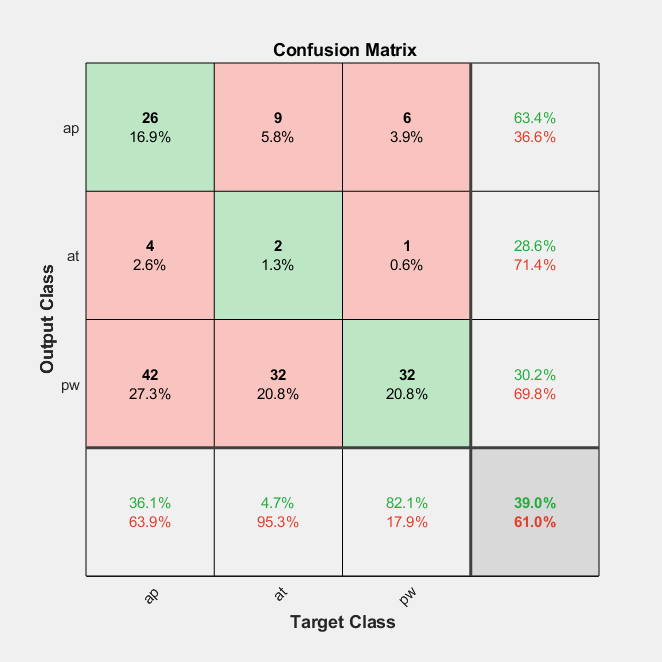

features_train_norm = normalize_features(features_train,features_train);
features_test_norm = normalize_features(features_test,features_train);

Network size: 293.5986 kB
Single-sample prediction time on CPU: 40.2931 ms
Mean accuracy: 38.2 %
Confidence Interval: [10, 70]


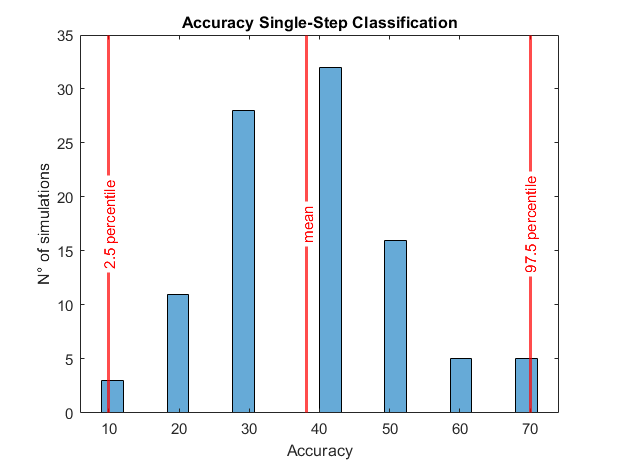


features_train = features_train_norm;
features_test = features_test_norm;

% Save features and labels to workspace
save(strcat('.\train_test_datasets\features_train_',task_selection,'.mat'),'features_train')

save(strcat('.\train_test_datasets\features_test_',task_selection,'.mat'),'features_test')
save(strcat('.\train_test_datasets\labels_train_',task_selection,'.mat'),'labels_train')
save(strcat('.\train_test_datasets\labels_test_',task_selection,'.mat'),'labels_test')

### 5.5 Principal Component Analysis

Not relevant, since we are extracting spectrograms from the audio signals and we are classifying them as images.

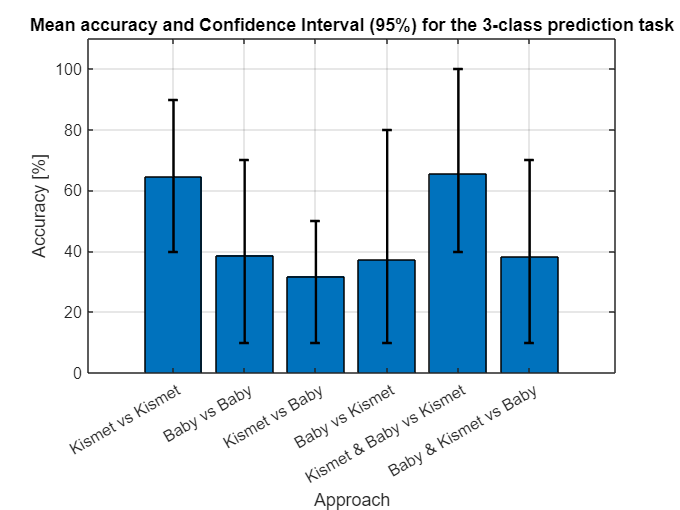

% num_feat = size(features_train{1},1);
% features_names = string(1:num_feat)';

% n_components = 10;
% pca_title = {'Principal Component Analysis','Kismet on Kismet Classification'};
% 
% PCA(cell2mat(features_train),pca_title,n_components,features_names);

## 6. Training of the Classifier

The Neural Network is trained and is saved, so that a different network for each different approach can be later tested on new data and evaluated.

load(strcat('features_train_',task_selection,'.mat'))
load(strcat('features_test_',task_selection,'.mat'))
load(strcat('labels_train_',task_selection,'.mat'))
load(strcat('labels_test_',task_selection,'.mat'))
load image_dims.mat     

% network_training            % Old function that uses spectral features and classifies them as sequences
network_training_spectrogram  % Classification using image recognition of spectrograms

## 7. Validation of Classifier Accuracy (Bootstrapping)

### 7.1 Compute Validation Accuracy and Plot Confusion Matrix

Validation accuracy and the corresponding confusion matrix are shown below. They are referred to a single run performed over the entire test dataset that has been provided to the network.

load(strcat('net_',task_selection,'.mat'))

predicted_labels = classify(net,features_test);

accuracy = (sum(predicted_labels == labels_test))/length(labels_test)*100
figure
plotconfusion(labels_test,predicted_labels)

### 7.2 Evaluate Network Size, Prediction Time and Accuracy using Bootstrapping

The performance of the network is evaluated in terms of:

- size

- average prediction time

- average prediction accuracy and confidence interval (95%)

100 runs are executed over randomly drawn subsets of the test samples, in order to average out results and obtain an accuracy distribution across multiple runs. The mean accuracy is then taken as the final metric for evaluating the network.

evaluate_performance

## 8. Comparison among different Approaches

The six different approaches are compared: mean accuracies and confidence intervals over multiple runs are shown. Under the same values of the parameters for network building and training and the same window length and overlap for the spectrogram extraction, it can be seen that results are generally very poor (mean accuracies ranging from 30% to 65%). It can be seen that the CI are very wide, meaning that accuracy results can vary a lot depending on the different test sub-datasets the net is provided with: the model generalizes badly, hence overfitting is an issue to deal with.

final_comparison

## Conclusions

This short work provides a framework for classifying audio signals through image recognition of their spectrogram. However, accuracy and generalization results are poor, hence improvements have to be made. The possible areas on which to intervene are:

- proper dataset selection for the training phase,

- better tuning of the network, both in terms of its structure and of the training options,

- more accurate feature extraction process, resulting in more meaningful features that allow for a better separation of the classes. In particular, a better tuning of the window length, overlap percent, frequency/time resolution can be carried out,

- different ways to preprocess signals, in order to better filter out irrelevant information and keep only the most meaningful portion of the recording.